## Regional air freight aircraft Specification

% Fixed Parameter
g = 9.81; % Gravity (kg/m^2)
Datum   = 11.5; % From Tip to Datum (m)
Crew    = 2;


% Measurments 
FuselageL = 24.2; % Fuselage length (m)
Wingspan  = 19.25; % (m)
WingA     = 32.51; % Wing Area (m^2)
ArW       = Wingspan^2/WingA; % Aspect Ratio of Wing
CabinL    = 14.1; % Cabin Length (m)

% Performance
OEW        = 8812; % (kg)
MTOW       = 16020*g; % (kg)
MaxPayload = 5290; % (kg)
MaxFuel    = 3600; % (kg)
DesignFuel = 1918; % (kg)
MLW        = 15570% * g; % (kg)

MLW = 15570


% Aircraft Masses
Wings          = 1573.6; % (kg)
HorizontalTail = 334.5; % (kg)
VerticalFin    = 289.9; % (kg)
Fuselage       = 5714; % (kg)

% Loading Gear loading Limits
FrontLG = 370; % Front Landing Gear (kg)
MainLG  = 18000; % Main Landing Gear (kg)

% Engine and Power
EngineW_1   = 450; % Engine 1 Weight (kg)
EngineW_2   = 450; % Engine 2 Weight (kg)
Fuelconsump = 0.485; % Fuel Consumption (lb/hp/hr)
SThrust     = 18550 * 2; % Static Thrust both Engine (N ISA)
PropD       = 3.5; % Propeller Diameter (m), variable pitch

Conversions 

Feet  = 3.2808399; % Conversion from meters to feet
Knots = 1.94384449; % conversion form m/s to kts

## Centre Of Gravity Limits

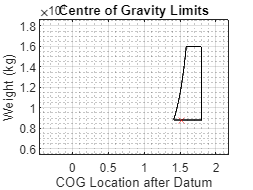

% Weight array and COG calculation
weight = 8812:10:16020;

RearG  = Datum + 1.8; % Rear Gear location on x axis
FrontG = Datum - 7.5; % Front Gear location on x axis
for   i=1:length(weight)
    cg = ((369.99 * (FrontG-RearG)./weight)+RearG) - Datum;
end
figure(1)
plot(cg, weight, 'color','black') % Front structrual limit 
hold off
%Graphing
hold on
plot([1.58510448413690 1.8], [16020 16020], 'color','black') % MTOW
plot([1.8 1.8], [8812 16020], 'color','black') % Rear Gear
plot([1.40952031320926 1.8], [8812 8812], 'color','black')
grid on; grid minor

ylabel('Weight (kg)')
xlabel('COG Location after Datum')
title('Centre of Gravity Limits')
xlim([-0.46 2.18])
ylim([5454 18631])

plot(1.525, 8812, 'rx')

Altitudes 

% Air Density at Different Altitudes (kg/m^3)
Ad_0    = 1.224995968060217;
Ad_2000 = 1.154899172335768;
Ad_4000 = 1.0879259769692413;
Ad_6000 = 1.023980271180393;
Ad_8000 = 0.9629659441889794;

% Temperature at Different Altitudes (Kelvin)
T_0    = 288.2;
T_2000 = 284.2;
T_4000 = 280.2;
T_6000 = 276.3;
T_8000 = 272.3;

% Speed of Sound at Different Altitudes (m/s)
SS_0    = 340.2957888; 
SS_2000 = 337.9443584;
SS_4000 = 335.5839872;
SS_6000 = 333.201264;
SS_8000 = 330.8051296;

## Take-Off Distance 

% Parameters
Re       = 1000000 % Reynalds number

Re = 1000000

e        = (1.78 * (1 - (0.045 * (ArW^0.68)))) - 0.64; % Oswalds Efficency Factor
k        = 1/(pi * ArW * e); % Ground induced drag
GR_Cl    = 0.035; % Ground run lift coefficient on dry asphalt
LcH      = 35 * 0.3048; % lift off Clearance height
Power    = 1625000 * 2; % Power of both engines (W)
Clmax_20 = 1.655; % Maximum lift Coefficient at 20 Deg flap Deflection (Javafoil)
Clmin    = GR_Cl/(2 * k); % Mimimum Ground run lift coefficient
Clmin_203D = (Clmin/(1+(Clmin/(pi * ArW * e)))); % Minimum 3D Coefficient of lift 
Clmax_203D = (Clmax_20/(1+(Clmax_20/(pi * ArW * e)))) % Maximum 3d Coefficient of lift

Clmax_203D = 1.5553

Cldelta  = Clmax_203D - Clmin_203D; % Differnce between Max and Min Lift Coefficient
Cd0      = 0.00909; % Coefficient of drag at 20 Deg flap Deflection (Javafoil)
Cd       = Cd0 + (k*(Clmax_20^2)); % Drag

% Take off at 0ft (Sea Level)

Vstall0 = sqrt((2 * MTOW)/(Ad_0 * Clmax_203D * WingA)) % Stall Speed VStall (m/s)

Vstall0 = 71.2359


LminV0 = 1.1 * Vstall0; % Minimum lift off Velocity (m/s)
LminK0 = LminV0 * 1.94384449 % Minimum lift off Velocity (kts)

LminK0 = 152.3186


ToV0   = 1.2 * Vstall0; % Take off Velocity at 35ft above altitude (m/s)
ToK0   = ToV0 * 1.94384449 % Take off Velocity (kts)

ToK0 = 166.1658


Vr0       = (1.2 * 1.05)/ 1.1 * Vstall0; % Rotational Take off Velocity 
Clmin_To0 = (MTOW/(0.5 * Ad_0 * (Vr0^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR0    = -(MTOW/(g * Ad_0 * WingA)) * (1/(Cd - (GR_Cl * Clmin_203D))) .* log(1 - (Cd - (GR_Cl * Clmin_203D))./((SThrust/MTOW - GR_Cl) * Clmin_To0)) % Ground Run Distance (m)

GroudR0 = 2.1857e+03

GroundRft0 = GroudR0 * 3.2808399 % Ground Run Distance (ft)

GroundRft0 = 7.1708e+03


M0       = LminV0 / SS_0 % Mach Number at 0ft

M0 = 0.2303

PropE0   = (2.97984 * M0) - (6.92675 * (M0^2)) + (19.1836 * (M0^3)) - (20.94595 * (M0^4)) % Propellor efficency (Function at Mach number)

PropE0 = 0.4942

ThrustA0 = (PropE0 * Power) / LminV0 % Thrust Avalible (N)

ThrustA0 = 2.0498e+04

D0      = 0.5 * Ad_0 * LminV0^2 * Cd * WingA % initial Drag

D0 = 1.4084e+04

AngLo0   = asin(ThrustA0 - D0/MTOW) % Lift off Angle Gamma

AngLo0 = 1.5708 - 10.6212i


LoAP0   = (((MTOW / WingA) * AngLo0) / (Ad_0 * g * Cldelta)) + (LcH / AngLo0) % Lift off Air Phase (m)

LoAP0 = 5.6874e+02 - 3.8437e+03i

LoAPft0 = LoAP0 * Feet % Lift off Air Phase (ft)

LoAPft0 = 1.8660e+03 - 1.2611e+04i

ToD0    = GroudR0 + LoAP0 % Total Take off Distance (m)

ToD0 = 2.7544e+03 - 3.8437e+03i

ToDft0  = ToD0 * Feet % Total Take off Distance (ft)

ToDft0 = 9.0368e+03 - 1.2611e+04i


% Take off at 2000ft

Vstall2000 = sqrt((2 * MTOW)/(Ad_2000 * Clmax_203D * WingA)) % Stall Speed VStall (m/s)

Vstall2000 = 73.3659


LminV2000 = 1.1 * Vstall2000; % Minimum lift off Velocity (m/s)
LminK2000 = LminV2000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK2000 = 156.8730


ToV2000   = 1.2 * Vstall2000; % Take off Velocity at 35ft above altitude (m/s)
ToK2000   = ToV2000 * 1.94384449 % Take off Velocity (kts)

ToK2000 = 171.1342


Vr2000       = (1.2 * 1.05)/ 1.1 * Vstall2000; % Rotational Take off Velocity 
Clmin_To2000 = (MTOW/(0.5 * Ad_2000 * (Vr2000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR2000    = -(MTOW/(g * Ad_2000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_203D))) .* log(1 - (Cd - (GR_Cl * Clmin_203D))./((SThrust/MTOW - GR_Cl) * Clmin_To2000)); % Ground Run Distance (m)
GroundRft2000 = GroudR2000 * 3.2808399 % Ground Run Distance (ft)

GroundRft2000 = 7.6060e+03


M2000       = LminV2000 / SS_2000 % Mach Number at 2000ft

M2000 = 0.2388

PropE2000   = (2.97984 * M2000) - (6.92675 * (M2000^2)) + (19.1836 * (M2000^3)) - (20.94595 * (M2000^4)) % Propellor efficency (Function at Mach number)

PropE2000 = 0.5097

ThrustA2000 = (PropE2000 * Power) / LminV2000 % Thrust Avalible (N)

ThrustA2000 = 2.0527e+04

D2000      = 0.5 * Ad_2000 * LminV2000^2 * Cd * WingA % initial Drag

D2000 = 1.4084e+04

AngLo2000   = asin(ThrustA2000 - D2000/MTOW) % Lift off Angle

AngLo2000 = 1.5708 - 10.6226i


LoAP2000   = (((MTOW / WingA) * AngLo2000) / (Ad_2000 * g * Cldelta)) + (LcH / AngLo2000) % Lift off Air Phase (m)

LoAP2000 = 6.0325e+02 - 4.0776e+03i

LoAPft2000 = LoAP2000 * Feet % Lift off Air Phase (ft)

LoAPft2000 = 1.9792e+03 - 1.3378e+04i

ToD2000    = GroudR2000 + LoAP2000 % Total Take off Distance (m)

ToD2000 = 2.9216e+03 - 4.0776e+03i

ToDft2000  = ToD2000 * Feet % Total Take off Distance (ft)

ToDft2000 = 9.5852e+03 - 1.3378e+04i


% Take off at 4000ft

Vstall4000 = sqrt((2 * MTOW)/(Ad_4000 * Clmax_203D * WingA)) % Stall Speed VStall (m/s)

Vstall4000 = 75.5904


LminV4000 = 1.1 * Vstall4000; % Minimum lift off Velocity (m/s)
LminK4000 = LminV4000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK4000 = 161.6295


ToV4000   = 1.2 * Vstall4000; % Take off Velocity at 35ft above altitude (m/s)
ToK4000   = ToV4000 * 1.94384449 % Take off Velocity (kts)

ToK4000 = 176.3231


Vr4000       = (1.2 * 1.05)/ 1.1 * Vstall4000; % Rotational Take off Velocity 
Clmin_To4000 = (MTOW/(0.5 * Ad_4000 * (Vr4000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR4000    = -(MTOW/(g * Ad_4000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_203D))) .* log(1 - (Cd - (GR_Cl * Clmin_203D))./((SThrust/MTOW - GR_Cl) * Clmin_To4000)); % Ground Run Distance (m)
GroundRft4000 = GroudR4000 * 3.2808399 % Ground Run Distance (ft)

GroundRft4000 = 8.0743e+03


M4000       = LminV4000 / SS_4000 % Mach Number at 4000ft

M4000 = 0.2478

PropE4000   = (2.97984 * M4000) - (6.92675 * (M4000^2)) + (19.1836 * (M4000^3)) - (20.94595 * (M4000^4)) % Propellor efficency (Function at Mach number)

PropE4000 = 0.5259

ThrustA4000 = (PropE4000 * Power) / LminV4000 % Thrust Avalible (N)

ThrustA4000 = 2.0557e+04

D4000      = 0.5 * Ad_4000 * LminV4000^2 * Cd * WingA % initial Drag

D4000 = 1.4084e+04

AngLo4000   = asin(ThrustA4000 - D4000/MTOW) % Lift off Angle

AngLo4000 = 1.5708 - 10.6241i


LoAP4000   = (((MTOW / WingA) * AngLo4000) / (Ad_4000 * g * Cldelta)) + (LcH / AngLo4000) % Lift off Air Phase (m)

LoAP4000 = 6.4038e+02 - 4.3293e+03i

LoAPft4000 = LoAP4000 * Feet % Lift off Air Phase (ft)

LoAPft4000 = 2.1010e+03 - 1.4204e+04i

ToD4000    = GroudR4000 + LoAP4000 % Total Take off Distance (m)

ToD4000 = 3.1014e+03 - 4.3293e+03i

ToDft4000  = ToD4000 * Feet % Total Take off Distance (ft)

ToDft4000 = 1.0175e+04 - 1.4204e+04i


% Take off at 6000ft

Vstall6000 = sqrt((2 * MTOW)/(Ad_6000 * Clmax_203D * WingA)) % Stall Speed VStall (m/s)

Vstall6000 = 77.9149


LminV6000 = 1.1 * Vstall6000; % Minimum lift off Velocity (m/s)
LminK6000 = LminV6000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK6000 = 166.5998


ToV6000   = 1.2 * Vstall6000; % Take off Velocity at 35ft above altitude (m/s)
ToK6000   = ToV6000 * 1.94384449 % Take off Velocity (kts)

ToK6000 = 181.7452


Vr6000       = (1.2 * 1.05)/ 1.1 * Vstall6000; % Rotational Take off Velocity 
Clmin_To6000 = (MTOW/(0.5 * Ad_6000 * (Vr6000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR6000    = -(MTOW/(g * Ad_6000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_203D))) .* log(1 - (Cd - (GR_Cl * Clmin_203D))./((SThrust/MTOW - GR_Cl) * Clmin_To6000)); % Ground Run Distance (m)
GroundRft6000 = GroudR6000 * 3.2808399 % Ground Run Distance (ft)

GroundRft6000 = 8.5785e+03


M6000       = LminV6000 / SS_6000 % Mach Number at 6000ft

M6000 = 0.2572

PropE6000   = (2.97984 * M6000) - (6.92675 * (M6000^2)) + (19.1836 * (M6000^3)) - (20.94595 * (M6000^4)) % Propellor efficency (Function at Mach number)

PropE6000 = 0.5430

ThrustA6000 = (PropE6000 * Power) / LminV6000 % Thrust Avalible (N)

ThrustA6000 = 2.0589e+04

D6000      = 0.5 * Ad_6000 * LminV6000^2 * Cd * WingA % initial Drag

D6000 = 1.4084e+04

AngLo6000   = asin(ThrustA6000 - D6000/MTOW) % Lift off Angle

AngLo6000 = 1.5708 - 10.6257i


LoAP6000   = (((MTOW / WingA) * AngLo6000) / (Ad_6000 * g * Cldelta)) + (LcH / AngLo6000) % Lift off Air Phase (m)

LoAP6000 = 6.8036e+02 - 4.6004e+03i

LoAPft6000 = LoAP6000 * Feet % Lift off Air Phase (ft)

LoAPft6000 = 2.2322e+03 - 1.5093e+04i

ToD6000    = GroudR6000 + LoAP6000 % Total Take off Distance (m)

ToD6000 = 3.2951e+03 - 4.6004e+03i

ToDft6000  = ToD6000 * Feet % Total Take off Distance (ft)

ToDft6000 = 1.0811e+04 - 1.5093e+04i


% Take off at 8000ft

Vstall8000 = sqrt((2 * MTOW)/(Ad_8000 * Clmax_203D * WingA)) % Stall Speed VStall (m/s)

Vstall8000 = 80.3453


LminV8000 = 1.1 * Vstall8000; % Minimum lift off Velocity (m/s)
LminK8000 = LminV8000 * 1.94384449 % Minimum lift off Velocity (kts)

LminK8000 = 171.7967


ToV8000   = 1.2 * Vstall8000; % Take off Velocity 35ft above altitude (m/s)
ToK8000   = ToV8000 * 1.94384449 % Take off Velocity (kts)

ToK8000 = 187.4146


Vr8000       = (1.2 * 1.05)/ 1.1 * Vstall8000; % Rotational Take off Velocity 
Clmin_To8000 = (MTOW/(0.5 * Ad_8000 * (Vr8000^2) * WingA)); % Minimum Coeffiecient of lift for take off 

GroudR8000    = -(MTOW/(g * Ad_8000 * WingA)) * (1/(Cd - (GR_Cl * Clmin_203D))) .* log(1 - (Cd - (GR_Cl * Clmin_203D))./((SThrust/MTOW - GR_Cl) * Clmin_To8000)); % Ground Run Distance (m)
GroundRft8000 = GroudR8000 * 3.2808399 % Ground Run Distance (ft)

GroundRft8000 = 9.1220e+03


M8000       = LminV8000 / SS_8000 % Mach Number at 8000ft

M8000 = 0.2672

PropE8000   = (2.97984 * M8000) - (6.92675 * M8000^2) + (19.1836 * M8000^3) - (20.94595 * M8000^4) % Propellor efficency (Function at Mach number)

PropE8000 = 0.5608

ThrustA8000 = (PropE8000 * Power) / LminV8000 % Thrust Avalible (N)

ThrustA8000 = 2.0623e+04

D8000      = 0.5 * Ad_8000 * LminV8000^2 * Cd * WingA % initial Drag

D8000 = 1.4084e+04

AngLo8000   = asin(ThrustA8000 - D8000/MTOW) % Lift off Angle

AngLo8000 = 1.5708 - 10.6273i


LoAP8000   = (((MTOW / WingA) * AngLo8000) / (Ad_8000 * g * Cldelta)) + (LcH / AngLo8000) % Lift off Air Phase (m)

LoAP8000 = 7.2346e+02 - 4.8927e+03i

LoAPft8000 = LoAP8000 * Feet % Lift off Air Phase (ft)

LoAPft8000 = 2.3736e+03 - 1.6052e+04i

ToD8000    = GroudR8000 + LoAP8000 % Total Take off Distance (m)

ToD8000 = 3.5039e+03 - 4.8927e+03i

ToDft8000  = ToD8000 * Feet % Total Take off Distance (ft)

ToDft8000 = 1.1496e+04 - 1.6052e+04i

## Climb Performance

% Fixed Parameters
Re        = 55000000 % Reynalds number

Re = 55000000

e         = (1.78 * (1 - (0.045 * (ArW^0.68)))) - 0.64; % Oswalds Efficency Factor
k         = 1/(pi * ArW * e); % Ground induced drag
GR_Cl     = 0.035; % Ground run lift coefficient on dry asphalt
LcH       = 35 * 0.3048; % lift off Clearance height
Power     = 16250 * 2; % Power of both engines (W)
RClmax    = 0.426; % Maximum lift Coefficient (Javafoil)
RClmin    = GR_Cl/(2 * k); % Mimimum Ground run lift coefficient
RClmin_3D = (RClmin/(1+(RClmin/(pi * ArW * e)))); % Minimum 3D Coefficient of lift 
RClmax_3D = (RClmax/(1+(RClmax/(pi * ArW * e)))) % Maximum 3d Coefficient of lift

RClmax_3D = 0.4191

RCldelta  = RClmax_3D - RClmin_3D; % Differnce between Max and Min Lift Coefficient
RCd_0     = 0.00556; % Coefficient of drag at 0 Deg flap Deflection (Javafoil)
RCd       = RCd_0 + (k*(RClmax^2)); % Drag
V_ROC     = linspace (0,300,1000) * Knots; % Velocity at Rate of climb (kts)
Cd_ROC    = RCd + (k * (RClmax^2)); % Coefficient of drag at Rate of Climb

% Rate of Climb Drag
DROC_0    = 0.5 * Ad_0 * (V_ROC.^2) * Cd_ROC * WingA % 0ft

DROC_0 = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0025    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032


DROC_2000 = 0.5 * Ad_2000 * (V_ROC.^2) * Cd_ROC * WingA % 2000ft

DROC_2000 = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0030


DROC_4000 = 0.5 * Ad_4000 * (V_ROC.^2) * Cd_ROC * WingA % 4000ft

DROC_4000 = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028


DROC_6000 = 0.5 * Ad_6000 * (V_ROC.^2) * Cd_ROC * WingA % 6000ft

DROC_6000 = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027


DROC_8000 = 0.5 * Ad_8000 * (V_ROC.^2) * Cd_ROC * WingA % 8000ft

DROC_8000 = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025



% Rate of Climb Mach number 
MROC_0       = V_ROC / SS_0 % 0ft

MROC_0 =          0    0.0017    0.0034    0.0051    0.0069    0.0086    0.0103    0.0120    0.0137    0.0154    0.0172    0.0189    0.0206    0.0223    0.0240    0.0257    0.0274    0.0292    0.0309    0.0326    0.0343    0.0360    0.0377    0.0395    0.0412    0.0429    0.0446    0.0463    0.0480    0.0497    0.0515    0.0532    0.0549    0.0566    0.0583    0.0600    0.0618    0.0635    0.0652    0.0669    0.0686    0.0703    0.0720    0.0738    0.0755    0.0772    0.0789    0.0806    0.0823    0.0841


MROC_2000    = V_ROC / SS_2000 % 2000ft

MROC_2000 =          0    0.0017    0.0035    0.0052    0.0069    0.0086    0.0104    0.0121    0.0138    0.0155    0.0173    0.0190    0.0207    0.0225    0.0242    0.0259    0.0276    0.0294    0.0311    0.0328    0.0345    0.0363    0.0380    0.0397    0.0415    0.0432    0.0449    0.0466    0.0484    0.0501    0.0518    0.0535    0.0553    0.0570    0.0587    0.0605    0.0622    0.0639    0.0656    0.0674    0.0691    0.0708    0.0725    0.0743    0.0760    0.0777    0.0795    0.0812    0.0829    0.0846


MROC_4000    = V_ROC / SS_4000 % 4000ft

MROC_4000 =          0    0.0017    0.0035    0.0052    0.0070    0.0087    0.0104    0.0122    0.0139    0.0157    0.0174    0.0191    0.0209    0.0226    0.0244    0.0261    0.0278    0.0296    0.0313    0.0330    0.0348    0.0365    0.0383    0.0400    0.0417    0.0435    0.0452    0.0470    0.0487    0.0504    0.0522    0.0539    0.0557    0.0574    0.0591    0.0609    0.0626    0.0644    0.0661    0.0678    0.0696    0.0713    0.0731    0.0748    0.0765    0.0783    0.0800    0.0818    0.0835    0.0852


MROC_6000    = V_ROC / SS_6000 % 6000ft

MROC_6000 =          0    0.0018    0.0035    0.0053    0.0070    0.0088    0.0105    0.0123    0.0140    0.0158    0.0175    0.0193    0.0210    0.0228    0.0245    0.0263    0.0280    0.0298    0.0315    0.0333    0.0350    0.0368    0.0385    0.0403    0.0420    0.0438    0.0455    0.0473    0.0491    0.0508    0.0526    0.0543    0.0561    0.0578    0.0596    0.0613    0.0631    0.0648    0.0666    0.0683    0.0701    0.0718    0.0736    0.0753    0.0771    0.0788    0.0806    0.0823    0.0841    0.0858


MROC_8000    = V_ROC / SS_8000 % 8000ft

MROC_8000 =          0    0.0018    0.0035    0.0053    0.0071    0.0088    0.0106    0.0124    0.0141    0.0159    0.0176    0.0194    0.0212    0.0229    0.0247    0.0265    0.0282    0.0300    0.0318    0.0335    0.0353    0.0371    0.0388    0.0406    0.0424    0.0441    0.0459    0.0476    0.0494    0.0512    0.0529    0.0547    0.0565    0.0582    0.0600    0.0618    0.0635    0.0653    0.0671    0.0688    0.0706    0.0723    0.0741    0.0759    0.0776    0.0794    0.0812    0.0829    0.0847    0.0865



% Propeller Efficiency
ROCPropE_0      = (2.97984 * MROC_0) - (6.92675 * (MROC_0.^2)) + (19.1836 * (MROC_0.^3)) - (20.94595 * (MROC_0.^4)) % 0ft

ROCPropE_0 =          0    0.0051    0.0101    0.0152    0.0201    0.0251    0.0300    0.0348    0.0396    0.0444    0.0492    0.0539    0.0586    0.0632    0.0678    0.0724    0.0770    0.0815    0.0859    0.0904    0.0948    0.0992    0.1036    0.1079    0.1122    0.1165    0.1207    0.1250    0.1292    0.1333    0.1375    0.1416    0.1457    0.1498    0.1538    0.1578    0.1618    0.1658    0.1697    0.1737    0.1776    0.1815    0.1853    0.1892    0.1930    0.1968    0.2006    0.2044    0.2081    0.2119


ROCPropE_2000   = (2.97984 * MROC_2000) - (6.92675 * (MROC_2000.^2)) + (19.1836 * (MROC_2000.^3)) - (20.94595 * (MROC_2000.^4)) % 2000ft

ROCPropE_2000 =          0    0.0051    0.0102    0.0153    0.0203    0.0252    0.0302    0.0351    0.0399    0.0447    0.0495    0.0542    0.0590    0.0636    0.0683    0.0729    0.0775    0.0820    0.0865    0.0910    0.0954    0.0999    0.1042    0.1086    0.1129    0.1172    0.1215    0.1258    0.1300    0.1342    0.1383    0.1425    0.1466    0.1507    0.1547    0.1588    0.1628    0.1668    0.1708    0.1747    0.1787    0.1826    0.1865    0.1903    0.1942    0.1980    0.2018    0.2056    0.2094    0.2131


ROCPropE_4000   = (2.97984 * MROC_4000) - (6.92675 * (MROC_4000.^2)) + (19.1836 * (MROC_4000.^3)) - (20.94595 * (MROC_4000.^4)) % 4000ft

ROCPropE_4000 =          0    0.0052    0.0103    0.0154    0.0204    0.0254    0.0304    0.0353    0.0402    0.0450    0.0498    0.0546    0.0594    0.0641    0.0687    0.0734    0.0780    0.0825    0.0871    0.0916    0.0961    0.1005    0.1049    0.1093    0.1137    0.1180    0.1223    0.1266    0.1308    0.1350    0.1392    0.1434    0.1475    0.1516    0.1557    0.1598    0.1638    0.1678    0.1718    0.1758    0.1798    0.1837    0.1876    0.1915    0.1954    0.1992    0.2031    0.2069    0.2107    0.2144


ROCPropE_6000   = (2.97984 * MROC_6000) - (6.92675 * (MROC_6000.^2)) + (19.1836 * (MROC_6000.^3)) - (20.94595 * (MROC_6000.^4)) % 6000ft

ROCPropE_6000 =          0    0.0052    0.0104    0.0155    0.0205    0.0256    0.0306    0.0355    0.0405    0.0453    0.0502    0.0550    0.0598    0.0645    0.0692    0.0739    0.0785    0.0831    0.0877    0.0922    0.0967    0.1012    0.1056    0.1100    0.1144    0.1188    0.1231    0.1274    0.1316    0.1359    0.1401    0.1443    0.1485    0.1526    0.1567    0.1608    0.1649    0.1689    0.1729    0.1769    0.1809    0.1849    0.1888    0.1927    0.1966    0.2005    0.2043    0.2081    0.2120    0.2158


ROCPropE_8000   = (2.97984 * MROC_8000) - (6.92675 * (MROC_8000.^2)) + (19.1836 * (MROC_8000.^3)) - (20.94595 * (MROC_8000.^4)) % 8000ft

ROCPropE_8000 =          0    0.0052    0.0104    0.0156    0.0207    0.0258    0.0308    0.0358    0.0407    0.0457    0.0505    0.0554    0.0602    0.0649    0.0697    0.0744    0.0790    0.0837    0.0883    0.0928    0.0973    0.1018    0.1063    0.1108    0.1152    0.1195    0.1239    0.1282    0.1325    0.1368    0.1410    0.1452    0.1494    0.1536    0.1577    0.1618    0.1659    0.1700    0.1740    0.1780    0.1820    0.1860    0.1900    0.1939    0.1978    0.2017    0.2056    0.2094    0.2133    0.2171



% Thrust Avalible
ROCTa_0    = (ROCPropE_0 * (Ad_0/Ad_0)* Power) % 0ft

ROCTa_0 = 1.0e+06 *

         0    0.0002    0.0003    0.0005    0.0007    0.0008    0.0010    0.0011    0.0013    0.0014    0.0016    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0026    0.0028    0.0029    0.0031    0.0032    0.0034    0.0035    0.0036    0.0038    0.0039    0.0041    0.0042    0.0043    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0058    0.0059    0.0060    0.0061    0.0063    0.0064    0.0065    0.0066    0.0068    0.0069


ROCTa_2000 = (ROCPropE_2000 * (Ad_2000/Ad_0)* Power) % 2000ft

ROCTa_2000 = 1.0e+06 *

         0    0.0002    0.0003    0.0005    0.0006    0.0008    0.0009    0.0011    0.0012    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0042    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0058    0.0059    0.0061    0.0062    0.0063    0.0064    0.0065


ROCTa_4000 = (ROCPropE_4000 * (Ad_4000/Ad_0)* Power) % 4000ft

ROCTa_4000 = 1.0e+06 *

         0    0.0001    0.0003    0.0004    0.0006    0.0007    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0028    0.0029    0.0030    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0050    0.0051    0.0052    0.0053    0.0054    0.0055    0.0056    0.0058    0.0059    0.0060    0.0061    0.0062


ROCTa_6000 = (ROCPropE_6000 * (Ad_6000/Ad_0)* Power) % 6000ft

ROCTa_6000 = 1.0e+06 *

         0    0.0001    0.0003    0.0004    0.0006    0.0007    0.0008    0.0010    0.0011    0.0012    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0056    0.0057    0.0058    0.0059


ROCTa_8000 = (ROCPropE_8000 * (Ad_8000/Ad_0)* Power) % 8000ft

ROCTa_8000 = 1.0e+06 *

         0    0.0001    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0054    0.0055



% ROC MTOW (16020kg)
ROC_0    = ((ROCTa_0 - DROC_0) .* V_ROC) / MTOW % 0ft

ROC_0 = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


ROC_2000 = ((ROCTa_2000 - DROC_2000) .* V_ROC) / MTOW % 2000ft

ROC_2000 = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


ROC_4000 = ((ROCTa_4000 - DROC_4000) .* V_ROC) / MTOW % 4000ft

ROC_4000 = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


ROC_6000 = ((ROCTa_6000 - DROC_6000) .* V_ROC) / MTOW % 6000ft

ROC_6000 = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


ROC_8000 = ((ROCTa_8000 - DROC_8000) .* V_ROC) / MTOW % 8000ft

ROC_8000 = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


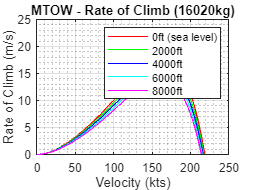


%  ROC Graph
figure(2)
plot(V_ROC, ROC_0, 'r')
hold on, grid on, grid minor
plot(V_ROC, ROC_2000, 'g')
plot(V_ROC, ROC_4000, 'b')
plot(V_ROC, ROC_6000, 'c')
plot(V_ROC, ROC_8000, 'm')
title('MTOW - Rate of Climb (16020kg)')
xlabel ('Velocity (kts)')
ylabel ('Rate of Climb (m/s)')
legend ('0ft (sea level)', '2000ft', '4000ft', '6000ft', '8000ft')

ylim ([0 25])
xlim ([0 250])

## **Cruise Performance**

Altitude

% Air Density at Different Altitudes (kg/m^3)
Ad_12000 = 0.8493309650141071;
Ad_14000 = 0.7965180912701609;
Ad_16000 = 0.7462841901294224;
Ad_18000 = 0.6985011138848998;
Ad_20000 = 0.653120807146471;

% Temperature at Different Altitudes (Kelvin)
T_12000  = 248.6;
T_14000  = 260.4;
T_16000  = 256.5;
T_18000  = 252.5;
T_20000  = 268.3;

% Speed of Sound at Different Altitudes (m/s)
SS_12000 = 325.9636864;
SS_14000 = 323.51390719999995;
SS_16000 = 321.0462464;
SS_18000 = 318.560704;
SS_20000 = 316.05728; 

% Fixed Parameters
Re        = 55000000 % Reynalds number

Re = 55000000

e         = (1.78 * (1 - (0.045 * (ArW^0.68)))) - 0.64; % Oswalds Efficency Factor
k         = 1/(pi * ArW * e); % Ground induced drag
GR_Cl     = 0.035; % Ground run lift coefficient on dry asphalt
LcH       = 35 * 0.3048; % lift off Clearance height
Power     = 1625000 * 2; % Power of both engines (W)
CClmax    = 0.426; % Maximum lift Coefficient (Javafoil)
CClmin    = GR_Cl/(2 * k); % Mimimum Ground run lift coefficient
CClmin_3D = (CClmin/(1+(CClmin/(pi * ArW * e)))); % Minimum 3D Coefficient of lift 
CClmax_3D = (CClmax/(1+(CClmax/(pi * ArW * e)))) % Maximum 3D Coefficient of lift

CClmax_3D = 0.4191

CCldelta  = CClmax_3D - CClmin_3D; % Differnce between Max and Min Lift Coefficient
CCd_0     = 0.00556; % Coefficient of drag at 0 Deg flap Deflection (Javafoil)
CCd       = CCd_0 + (k*(CClmax^2)); % Drag
V_Cruise  = linspace (0,340,1000) ; % Velocity at Rate of climb (m/s)

% Cruise Mach number 
MCruise_12000 = V_Cruise / SS_12000 % 12000ft

MCruise_12000 =          0    0.0010    0.0021    0.0031    0.0042    0.0052    0.0063    0.0073    0.0084    0.0094    0.0104    0.0115    0.0125    0.0136    0.0146    0.0157    0.0167    0.0177    0.0188    0.0198    0.0209    0.0219    0.0230    0.0240    0.0251    0.0261    0.0271    0.0282    0.0292    0.0303    0.0313    0.0324    0.0334    0.0345    0.0355    0.0365    0.0376    0.0386    0.0397    0.0407    0.0418    0.0428    0.0439    0.0449    0.0459    0.0470    0.0480    0.0491    0.0501    0.0512


MCruise_14000 = V_Cruise / SS_14000 % 14000ft

MCruise_14000 =          0    0.0011    0.0021    0.0032    0.0042    0.0053    0.0063    0.0074    0.0084    0.0095    0.0105    0.0116    0.0126    0.0137    0.0147    0.0158    0.0168    0.0179    0.0189    0.0200    0.0210    0.0221    0.0231    0.0242    0.0252    0.0263    0.0274    0.0284    0.0295    0.0305    0.0316    0.0326    0.0337    0.0347    0.0358    0.0368    0.0379    0.0389    0.0400    0.0410    0.0421    0.0431    0.0442    0.0452    0.0463    0.0473    0.0484    0.0494    0.0505    0.0515


MCruise_16000 = V_Cruise / SS_16000 % 16000ft

MCruise_16000 =          0    0.0011    0.0021    0.0032    0.0042    0.0053    0.0064    0.0074    0.0085    0.0095    0.0106    0.0117    0.0127    0.0138    0.0148    0.0159    0.0170    0.0180    0.0191    0.0201    0.0212    0.0223    0.0233    0.0244    0.0254    0.0265    0.0276    0.0286    0.0297    0.0307    0.0318    0.0329    0.0339    0.0350    0.0360    0.0371    0.0382    0.0392    0.0403    0.0413    0.0424    0.0435    0.0445    0.0456    0.0466    0.0477    0.0488    0.0498    0.0509    0.0519


MCruise_18000 = V_Cruise / SS_18000 % 18000ft

MCruise_18000 =          0    0.0011    0.0021    0.0032    0.0043    0.0053    0.0064    0.0075    0.0085    0.0096    0.0107    0.0118    0.0128    0.0139    0.0150    0.0160    0.0171    0.0182    0.0192    0.0203    0.0214    0.0224    0.0235    0.0246    0.0256    0.0267    0.0278    0.0288    0.0299    0.0310    0.0321    0.0331    0.0342    0.0353    0.0363    0.0374    0.0385    0.0395    0.0406    0.0417    0.0427    0.0438    0.0449    0.0459    0.0470    0.0481    0.0491    0.0502    0.0513    0.0524


MCruise_20000 = V_Cruise / SS_20000 % 20000ft

MCruise_20000 =          0    0.0011    0.0022    0.0032    0.0043    0.0054    0.0065    0.0075    0.0086    0.0097    0.0108    0.0118    0.0129    0.0140    0.0151    0.0162    0.0172    0.0183    0.0194    0.0205    0.0215    0.0226    0.0237    0.0248    0.0258    0.0269    0.0280    0.0291    0.0302    0.0312    0.0323    0.0334    0.0345    0.0355    0.0366    0.0377    0.0388    0.0398    0.0409    0.0420    0.0431    0.0442    0.0452    0.0463    0.0474    0.0485    0.0495    0.0506    0.0517    0.0528



% Propeller Efficiency

CPropE_12000   = (2.97984 * MCruise_12000) - (6.92675 * (MCruise_12000.^2)) + (19.1836 * (MCruise_12000.^3)) - (20.94595 * (MCruise_12000.^4)) % 12000ft

CPropE_12000 =          0    0.0031    0.0062    0.0093    0.0123    0.0154    0.0184    0.0214    0.0244    0.0274    0.0304    0.0333    0.0363    0.0392    0.0421    0.0450    0.0479    0.0508    0.0537    0.0565    0.0594    0.0622    0.0650    0.0678    0.0706    0.0734    0.0762    0.0789    0.0817    0.0844    0.0871    0.0898    0.0925    0.0952    0.0979    0.1005    0.1032    0.1058    0.1085    0.1111    0.1137    0.1163    0.1189    0.1215    0.1240    0.1266    0.1292    0.1317    0.1342    0.1367


CPropE_14000   = (2.97984 * MCruise_14000) - (6.92675 * (MCruise_14000.^2)) + (19.1836 * (MCruise_14000.^3)) - (20.94595 * (MCruise_14000.^4)) % 14000ft

CPropE_14000 =          0    0.0031    0.0062    0.0093    0.0124    0.0155    0.0185    0.0216    0.0246    0.0276    0.0306    0.0336    0.0366    0.0395    0.0424    0.0454    0.0483    0.0512    0.0541    0.0569    0.0598    0.0627    0.0655    0.0683    0.0711    0.0739    0.0767    0.0795    0.0822    0.0850    0.0877    0.0905    0.0932    0.0959    0.0986    0.1012    0.1039    0.1066    0.1092    0.1119    0.1145    0.1171    0.1197    0.1223    0.1249    0.1275    0.1300    0.1326    0.1351    0.1377


CPropE_16000   = (2.97984 * MCruise_16000) - (6.92675 * (MCruise_16000.^2)) + (19.1836 * (MCruise_16000.^3)) - (20.94595 * (MCruise_16000.^4)) % 16000ft

CPropE_16000 =          0    0.0032    0.0063    0.0094    0.0125    0.0156    0.0187    0.0217    0.0248    0.0278    0.0308    0.0338    0.0368    0.0398    0.0428    0.0457    0.0486    0.0516    0.0545    0.0574    0.0602    0.0631    0.0660    0.0688    0.0716    0.0745    0.0773    0.0801    0.0828    0.0856    0.0884    0.0911    0.0938    0.0966    0.0993    0.1020    0.1047    0.1073    0.1100    0.1127    0.1153    0.1179    0.1206    0.1232    0.1258    0.1284    0.1309    0.1335    0.1361    0.1386


CProPE_18000   = (2.97984 * MCruise_18000) - (6.92675 * (MCruise_18000.^2)) + (19.1836 * (MCruise_18000.^3)) - (20.94595 * (MCruise_18000.^4)) % 18000ft

CProPE_18000 =          0    0.0032    0.0063    0.0095    0.0126    0.0157    0.0188    0.0219    0.0250    0.0280    0.0311    0.0341    0.0371    0.0401    0.0431    0.0461    0.0490    0.0519    0.0549    0.0578    0.0607    0.0636    0.0665    0.0693    0.0722    0.0750    0.0778    0.0806    0.0834    0.0862    0.0890    0.0918    0.0945    0.0973    0.1000    0.1027    0.1054    0.1081    0.1108    0.1135    0.1161    0.1188    0.1214    0.1240    0.1267    0.1293    0.1319    0.1345    0.1370    0.1396


CPropE_20000   = (2.97984 * MCruise_20000) - (6.92675 * (MCruise_20000.^2)) + (19.1836 * (MCruise_20000.^3)) - (20.94595 * (MCruise_20000.^4)) % 20000ft

CPropE_20000 =          0    0.0032    0.0064    0.0096    0.0127    0.0158    0.0190    0.0221    0.0252    0.0282    0.0313    0.0344    0.0374    0.0404    0.0434    0.0464    0.0494    0.0523    0.0553    0.0582    0.0612    0.0641    0.0670    0.0698    0.0727    0.0756    0.0784    0.0812    0.0841    0.0869    0.0897    0.0924    0.0952    0.0980    0.1007    0.1035    0.1062    0.1089    0.1116    0.1143    0.1170    0.1196    0.1223    0.1249    0.1276    0.1302    0.1328    0.1354    0.1380    0.1406


Power avalible - Power reuquired - 12000ft

% 100% Throttle 
Pa12000_100 = (CPropE_12000 * (Ad_12000/Ad_0) * Power)  % Power avalible 

Pa12000_100 = 1.0e+07 *

         0    0.0007    0.0014    0.0021    0.0028    0.0035    0.0041    0.0048    0.0055    0.0062    0.0068    0.0075    0.0082    0.0088    0.0095    0.0101    0.0108    0.0115    0.0121    0.0127    0.0134    0.0140    0.0147    0.0153    0.0159    0.0165    0.0172    0.0178    0.0184    0.0190    0.0196    0.0202    0.0208    0.0215    0.0221    0.0227    0.0233    0.0238    0.0244    0.0250    0.0256    0.0262    0.0268    0.0274    0.0280    0.0285    0.0291    0.0297    0.0302    0.0308


Pr12000_100 = 0.5 * Ad_12000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_12000 .* V_Cruise * WingA))) % Power Required

Pr12000_100 = 1.0e+08 *

       Inf    2.0361    1.0180    0.6787    0.5090    0.4072    0.3393    0.2909    0.2545    0.2262    0.2036    0.1851    0.1697    0.1566    0.1454    0.1357    0.1273    0.1198    0.1131    0.1072    0.1018    0.0970    0.0926    0.0885    0.0848    0.0814    0.0783    0.0754    0.0727    0.0702    0.0679    0.0657    0.0636    0.0617    0.0599    0.0582    0.0566    0.0550    0.0536    0.0522    0.0509    0.0497    0.0485    0.0474    0.0463    0.0452    0.0443    0.0433    0.0424    0.0416



% 90% Throttle
Pa12000_90 = (CPropE_12000 * (Ad_12000/Ad_0) * Power) * 0.9; % Power avalible 
Pr12000_90 = 0.5 * Ad_12000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_12000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa12000_80 = (CPropE_12000 * (Ad_12000/Ad_0) * Power) * 0.8; % Power avalible 
Pr12000_80 = 0.5 * Ad_12000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_12000 .* V_Cruise * WingA))); % Power Required

Power avalible - Power reuquired - 14000ft

% 100% Throttle 
Pa14000_100 = (CPropE_14000 * (Ad_14000/Ad_0) * Power); % Power avalible 
Pr14000_100 = 0.5 * Ad_14000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_14000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa14000_90 = (CPropE_14000 * (Ad_14000/Ad_0) * Power) * 0.9; % Power avalible 
Pr14000_90 = 0.5 * Ad_14000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_14000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa14000_80 = (CPropE_14000 * (Ad_14000/Ad_0) * Power) * 0.8; % Power avalible 
Pr14000_80 = 0.5 * Ad_14000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_14000 .* V_Cruise * WingA))); % Power Required

Power avalible - Power reuquired -16000ft

% 100% Throttle 
Pa16000_100 = (CPropE_16000 * (Ad_16000/Ad_0) * Power); % Power avalible 
Pr16000_100 = 0.5 * Ad_16000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_16000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa16000_90 = (CPropE_16000 * (Ad_16000/Ad_0) * Power) * 0.9; % Power avalible 
Pr16000_90 = 0.5 * Ad_16000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_16000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa16000_80 = (CPropE_16000 * (Ad_16000/Ad_0) * Power) * 0.8; % Power avalible 
Pr16000_80 = 0.5 * Ad_16000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_16000 .* V_Cruise * WingA))); % Power Required

Power avalible - Power reuquired - 18000ft

% 100% Throttle 
Pa18000_100 = (CProPE_18000 * (Ad_18000/Ad_0) * Power); % Power avalible
Pr18000_100 = 0.5 * Ad_18000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_18000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa18000_90 = (CProPE_18000 * (Ad_18000/Ad_0) * Power) * 0.9; % Power avalible
Pr18000_90 = 0.5 * Ad_18000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_18000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa18000_80 = (CProPE_18000 * (Ad_18000/Ad_0) * Power) * 0.8; % Power avalible
Pr18000_80 = 0.5 * Ad_18000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_18000 .* V_Cruise * WingA))); % Power Required

Power avalible - Power reuquired - 20000ft

% 100% Throttle 
Pa20000_100 = (CPropE_20000 * (Ad_20000/Ad_0) * Power); % Power avalible 
Pr20000_100 = 0.5 * Ad_20000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_20000 .* V_Cruise * WingA))); % Power Required

% 90% Throttle
Pa20000_90 = (CPropE_20000 * (Ad_20000/Ad_0) * Power) * 0.9; % Power avalible 
Pr20000_90 = 0.5 * Ad_20000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_20000 .* V_Cruise * WingA))); % Power Required

% 80% Throttle 
Pa20000_80 = (CPropE_20000 * (Ad_20000/Ad_0) * Power) * 0.8; % Power avalible 
Pr20000_80 = 0.5 * Ad_20000 .* (V_Cruise.^3) * WingA * CCd_0 + (k * ((MTOW^2)./ (0.5 * Ad_20000 .* V_Cruise * WingA))); % Power Required

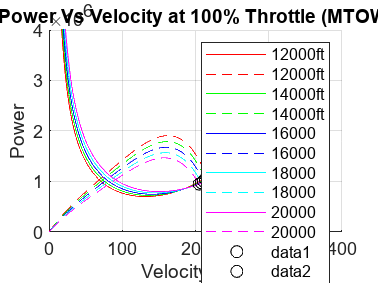

% Graph showing Power Vs velocity at 100% Throttle
figure(20)
grid on, hold on 
plot(V_Cruise, Pr12000_100, 'r', V_Cruise, Pa12000_100, '--', 'Color', 'r')
plot(V_Cruise, Pr14000_100, 'g', V_Cruise, Pa14000_100, '--', 'Color', 'g')
plot(V_Cruise, Pr16000_100, 'b', V_Cruise, Pa16000_100, '--', 'Color', 'b')
plot(V_Cruise, Pr18000_100, 'c', V_Cruise, Pa18000_100, '--', 'Color', 'c')
plot(V_Cruise, Pr20000_100, 'm', V_Cruise, Pa20000_100, '--', 'Color', 'm')
title('Power Vs Velocity at 100% Throttle (MTOW)')
xlabel('Velocity (kts)')
ylabel('Power')
legend('12000ft', '12000ft', '14000ft', '14000ft', '16000', '16000', '18000', '18000', '20000', '20000')

plot(215.435, 1093750, 'o', 'Color', 'black')
plot(213.393, 1045790, 'o', 'Color', 'black')
plot(210.671, 1008820, 'o', 'Color', 'black')
plot(207.948, 975501, 'o', 'Color', 'black')
plot(204.885, 949275, 'o', 'Color', 'black')

xlim([0 400])
ylim([0 4000000])

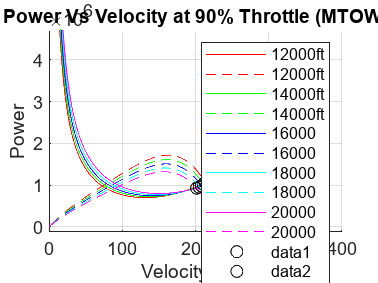

% Graph showing Power Vs Velocity at 90% Throttle
figure(21)
grid on, hold on 
plot(V_Cruise, Pr12000_90, 'r', V_Cruise, Pa12000_90, '--', 'Color', 'r')
plot(V_Cruise, Pr14000_90, 'g', V_Cruise, Pa14000_90, '--', 'Color', 'g')
plot(V_Cruise, Pr16000_90, 'b', V_Cruise, Pa16000_90, '--', 'Color', 'b')
plot(V_Cruise, Pr18000_90, 'c', V_Cruise, Pa18000_90, '--', 'Color', 'c')
plot(V_Cruise, Pr20000_90, 'm', V_Cruise, Pa20000_90, '--', 'Color', 'm')
title('Power Vs Velocity at 90% Throttle (MTOW)')
xlabel('Velocity (kts)')
ylabel('Power')
legend('12000ft', '12000ft', '14000ft', '14000ft', '16000', '16000', '18000', '18000', '20000', '20000')

plot(212.713, 1069570, 'o', 'Color', 'black')
plot(210.33, 1021140, 'o', 'Color', 'black')
plot(207.948, 980609, 'o', 'Color', 'black')
plot(204.885, 952172, 'o', 'Color', 'black')
plot(201.481, 928281, 'o', 'Color', 'black')

xlim([0 400])
ylim([0 4000000])

xlim([0 400])
ylim([-122233 4717767])

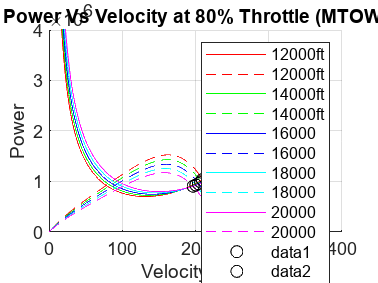

% Graph showing Power Vs Velocity at 80% Throttle
figure(22)
grid on, hold on 
plot(V_Cruise, Pr12000_80, 'r', V_Cruise, Pa12000_80, '--', 'Color', 'r')
plot(V_Cruise, Pr14000_80, 'g', V_Cruise, Pa14000_80, '--', 'Color', 'g')
plot(V_Cruise, Pr16000_80, 'b', V_Cruise, Pa16000_80, '--', 'Color', 'b')
plot(V_Cruise, Pr18000_80, 'c', V_Cruise, Pa18000_80, '--', 'Color', 'c')
plot(V_Cruise, Pr20000_80, 'm', V_Cruise, Pa20000_80, '--', 'Color', 'm')
title('Power Vs Velocity at 80% Throttle (MTOW)')
xlabel('Velocity (kts)')
ylabel('Power')
legend('12000ft', '12000ft', '14000ft', '14000ft', '16000', '16000', '18000', '18000', '20000', '20000')

plot(209.309, 1037320, 'o', 'Color', 'black')
plot(206.927, 991063, 'o', 'Color', 'black')
plot(203.864, 959046, 'o', 'Color', 'black')
plot(200.46, 931142, 'o', 'Color', 'black')
plot(196.717, 905713, 'o', 'Color', 'black')

xlim([0 400])
ylim([0 4000000])

Fuel consumption 

% 12000ft
CPmax_12000 = [1093750 1069570 1069570] % Maximum power at each Throttle speed(100%, 90%, 80%)

CPmax_12000 =      1093750     1069570     1069570


Fuelc_12000 = ((Fuelconsump * 0.45359237)/ 745.699872) .* CPmax_12000 % Fuel consumption (kg/hr/W) (converted from lb/hr/hp)

Fuelc_12000 =   322.6721  315.5387  315.5387



% 14000ft
CPmax_14000 = [1045790 1021140 1021140] % Maximum power at each Throttle speed (100%, 90%, 80%)

CPmax_14000 =      1045790     1021140     1021140


Fuelc_14000 = ((Fuelconsump * 0.45359237)/ 745.699872) .* CPmax_14000 % Fuel consumption (kg/hr/W) (converted from lb/hr/hp)

Fuelc_14000 =   308.5232  301.2511  301.2511



% 16000ft
CPmax_16000 = [1008820 980609 959046] % Maximum power at each Throttle speed(100%, 90%, 80%)

CPmax_16000 =      1008820      980609      959046


Fuelc_16000 = ((Fuelconsump * 0.45359237)/ 745.699872) .* CPmax_16000 % Fuel consumption (kg/hr/W) (converted from lb/hr/hp)

Fuelc_16000 =   297.6166  289.2939  282.9325



% 18000ft
CPmax_18000 = [975501 952172 931142] % Maximum power at each Throttle speed (100%, 90%, 80%)

CPmax_18000 =       975501      952172      931142


Fuelc_18000 = ((Fuelconsump * 0.45359237)/ 745.699872) .* CPmax_18000 % Fuel consumption (kg/hr/W) (converted from lb/hr/hp)

Fuelc_18000 =   287.7870  280.9046  274.7004



% 20000ft
CPmax_20000 = [949275 928281 928281] % Maximum power at each Throttle speed (100%, 90%, 80%)

CPmax_20000 =       949275      928281      928281


Fuelc_20000 = ((Fuelconsump * 0.45359237)/ 745.699872) .* CPmax_20000 % Fuel consumption (kg/hr/W) (converted from lb/hr/hp)

Fuelc_20000 =   280.0499  273.8564  273.8564


## Landing

% Fixed Parameters 
Clmax_35   = 1.916; % Maximum coefficient of lift at 35 deg flap deflection (AoA -9 deg)
Clmax_353D = (Clmax_35/(1 + (Clmax_35/(pi * ArW * e)))); % Maximum 3D Coefficient of lift
Cd0_35     = 0.00680; % Coefficient of Drag at 35 deg flap deflection (AoA -9 deg)
Gr_Braking = 0.45; % Ground run Drag coefficient on dry asphalt
LandcH       = 50 * 0.3048; % landing Clearance height

% Landing at 0ft (Sea Level)
LV_stall_0 = sqrt((2 * (g * MLW) / (Ad_0 *Clmax_353D  * WingA))) % Landing velocity stall

LV_stall_0 = 65.5792

AppV_0   = 1.3 * LV_stall_0; % Approaching velocity (m/s)
AppK_0   = AppV_0 * Knots % Approaching velocity (kts)

AppK_0 = 165.7186


LandV_0  = 0.95 * AppV_0; % Landing velocity at 50ft above altitude (m/s)
LandK_0  = LandV_0 * Knots % Landing velocity at 50ft above altitude (kts)

LandK_0 = 157.4327

LandL_0  = 0.5 * Ad_0 * (AppV_0^2) * Clmax_353D * WingA % Landing lift

LandL_0 = 2.5813e+05


LGround_d0    = (LandV_0^2) / (2 * g * Gr_Braking) % Ground Deceleration Distance (m)

LGround_d0 = 742.9425

LGroundft_d0  = LGround_d0 * Feet % Ground Deceleration Distance (ft)

LGroundft_d0 = 2.4375e+03


LandM0      = AppV_0 / SS_0 % Mach Number at 0ft

LandM0 = 0.2505

LPropE0     = (2.97984 * LandM0) - (6.92675 * (LandM0^2)) + (19.1836 * (LandM0^3)) - (20.94595 * (LandM0^4)) % Propellor efficency (Function at Mach number)

LPropE0 = 0.5309

LThrustA0   = (LPropE0 * Power) / AppV_0 % Landing Thrust  (N)

LThrustA0 = 2.0239e+04

LThrustU0   = LThrustA0 * 0.6 % Thrust used at land (N)

LThrustU0 = 1.2144e+04

LD_0        = 0.5 * Ad_0 * (AppV_0^2) * Cd0_35 * WingA % Landing Drag

LD_0 = 984.1246

Deff_0      = LThrustU0 - LD_0 % Effective drag

Deff_0 = 1.1159e+04

LAcc_0      = Deff_0 / MLW * g % Acceleration

LAcc_0 = 7.0311


LandAD_0   = (LandcH * (LandL_0 / Deff_0)) + (((AppV_0^2) - (LandV_0))/ (2 *LAcc_0)) % Landing Distance in air (m) (From 50ft)

LandAD_0 = 863.6147

LandADft_0 = LandAD_0 * Feet % Landing Distance in air (ft) (From 50ft)

LandADft_0 = 2.8334e+03

LandD_0    = LandAD_0 + LGround_d0 % Total Landing Distance (m)

LandD_0 = 1.6066e+03

LandDft_0  = LandD_0 * Feet % Total Landing Distance (ft)

LandDft_0 = 5.2709e+03


% Landing at 2000ft 
LV_stall_2000 = sqrt((2 * (g * MLW) / (Ad_2000 *Clmax_353D  * WingA))) % Landing velocity stall

LV_stall_2000 = 67.5401

AppV_2000   = 1.3 * LV_stall_2000; % Approaching velocity (m/s)
AppK_2000   = AppV_2000 * Knots % Approaching velocity (kts)

AppK_2000 = 170.6737


LandV_2000  = 0.95 * AppV_2000; % Landing velocity at 50ft above altitude (m/s)
LandK_2000  = LandV_2000 * Knots % Landing velocity at 50ft above altitude (kts)

LandK_2000 = 162.1400

LandL_2000  = 0.5 * Ad_2000 * (AppV_2000^2) * Clmax_353D * WingA % Landing lift

LandL_2000 = 2.5813e+05


LGround_d2000     = (LandV_2000^2) / (2 * g * Gr_Braking) % Ground Deceleration Distance (m)

LGround_d2000 = 788.0356

LGroundft_d2000  = LGround_d2000 * Feet % Ground Deceleration Distance (ft)

LGroundft_d2000 = 2.5854e+03


LandM2000      = AppV_2000 / SS_2000 % Mach Number at 2000ft

LandM2000 = 0.2598

LPropE2000     = (2.97984 * LandM2000) - (6.92675 * (LandM2000^2)) + (19.1836 * (LandM2000^3)) - (20.94595 * (LandM2000^4)) % Propellor efficency (Function at Mach number)

LPropE2000 = 0.5476

LThrustA2000   = (LPropE2000 * Power) / AppV_2000 % Landing Thrust  (N)

LThrustA2000 = 2.0270e+04

LThrustU2000   = LThrustA2000 * 0.6 % Thrust used at land (N)

LThrustU2000 = 1.2162e+04

LD_2000        = 0.5 * Ad_2000 * (AppV_2000^2) * Cd0_35 * WingA % Landing Drag

LD_2000 = 984.1246

Deff_2000      = LThrustU2000 - LD_2000 % Effective drag

Deff_2000 = 1.1178e+04

LAcc_2000      = Deff_2000 / MLW * g % Acceleration

LAcc_2000 = 7.0429


LandAD_2000   = (LandcH * (LandL_2000 / Deff_2000)) + (((AppV_2000^2) - (LandV_2000))/ (2 *LAcc_2000)) % Landing Distance in air (From 50ft)

LandAD_2000 = 893.3186

LandADft_2000 = LandAD_2000 * Feet % Landing Distance in air (ft) (From 50ft)

LandADft_2000 = 2.9308e+03

LandD_2000    = LandAD_2000 + LGround_d2000 % Total Landing Distance (m)

LandD_2000 = 1.6814e+03

LandDft_2000  = LandD_2000 * Feet % Total Landing Distance (ft)

LandDft_2000 = 5.5163e+03


% Landing at 4000ft 
LV_stall_4000 = sqrt((2 * (g * MLW) / (Ad_4000 *Clmax_353D  * WingA))) % Landing velocity stall

LV_stall_4000 = 69.5880

AppV_4000   = 1.3 * LV_stall_4000; % Approaching velocity (m/s)
AppK_4000   = AppV_4000 * Knots % Approaching velocity (kts)

AppK_4000 = 175.8486


LandV_4000  = 0.95 * AppV_4000; % Landing velocity at 50ft above altitude (m/s)
LandK_4000  = LandV_4000 * Knots % Landing velocity at 50ft above altitude (kts)

LandK_4000 = 167.0562

LandL_4000  = 0.5 * Ad_4000 * (AppV_4000^2) * Clmax_353D * WingA % Landing lift

LandL_4000 = 2.5813e+05


LGround_d4000     = (LandV_4000^2) / (2 * g * Gr_Braking) % Ground Deceleration Distance (m)

LGround_d4000 = 836.5474

LGroundft_d4000  = LGround_d4000 * Feet % Ground Deceleration Distance (ft)

LGroundft_d4000 = 2.7446e+03


LandM4000      = AppV_4000 / SS_4000 % Mach Number at 4000ft

LandM4000 = 0.2696

LPropE4000     = (2.97984 * LandM4000) - (6.92675 * (LandM4000^2)) + (19.1836 * (LandM4000^3)) - (20.94595 * (LandM4000^4)) % Propellor efficency (Function at Mach number)

LPropE4000 = 0.5651

LThrustA4000   = (LPropE4000 * Power) / AppV_4000 % Landing Thrust  (N)

LThrustA4000 = 2.0302e+04

LThrustU4000   = LThrustA4000 * 0.6 % Thrust used at land (N)

LThrustU4000 = 1.2181e+04

LD_4000        = 0.5 * Ad_4000 * (AppV_4000^2) * Cd0_35 * WingA % Landing Drag

LD_4000 = 984.1246

Deff_4000      = LThrustU4000 - LD_4000 % Effective drag

Deff_4000 = 1.1197e+04

LAcc_4000      = Deff_4000 / MLW * g % Acceleration

LAcc_4000 = 7.0548


LandAD_4000   = (LandcH * (LandL_4000 / Deff_4000)) + (((AppV_4000^2) - (LandV_4000))/ (2 *LAcc_4000)) % Landing Distance in air (From 50ft)

LandAD_4000 = 925.2635

LandADft_4000 = LandAD_4000 * Feet % Landing Distance in air (ft) (From 50ft)

LandADft_4000 = 3.0356e+03

LandD_4000    = LandAD_4000 + LGround_d4000 % Total Landing Distance (m)

LandD_4000 = 1.7618e+03

LandDft_4000  = LandD_4000 * Feet % Total Landing Distance (ft)

LandDft_4000 = 5.7802e+03


% Landing at 6000ft 
LV_stall_6000 = sqrt((2 * (g * MLW) / (Ad_6000 *Clmax_353D  * WingA))) % Landing velocity stall

LV_stall_6000 = 71.7279

AppV_6000   = 1.3 * LV_stall_6000; % Approaching velocity (m/s)
AppK_6000   = AppV_6000 * Knots % Approaching velocity (kts)

AppK_6000 = 181.2562


LandV_6000  = 0.95 * AppV_6000; % Landing velocity at 50ft above altitude (m/s)
LandK_6000  = LandV_6000 * Knots % Landing velocity at 50ft above altitude (kts)

LandK_6000 = 172.1934

LandL_6000  = 0.5 * Ad_6000 * (AppV_6000^2) * Clmax_353D * WingA % Landing lift

LandL_6000 = 2.5813e+05


LGround_d6000     = (LandV_6000^2) / (2 * g * Gr_Braking) % Ground Deceleration Distance (m)

LGround_d6000 = 888.7882

LGroundft_d6000  = LGround_d6000 * Feet % Ground Deceleration Distance (ft)

LGroundft_d6000 = 2.9160e+03


LandM6000      = AppV_6000 / SS_6000 % Mach Number at 0ft

LandM6000 = 0.2798

LPropE6000     = (2.97984 * LandM6000) - (6.92675 * (LandM6000^2)) + (19.1836 * (LandM6000^3)) - (20.94595 * (LandM6000^4)) % Propellor efficency (Function at Mach number)

LPropE6000 = 0.5834

LThrustA6000   = (LPropE6000 * Power) / AppV_6000 % Landing Thrust  (N)

LThrustA6000 = 2.0334e+04

LThrustU6000   = LThrustA6000 * 0.6 % Thrust used at land (N)

LThrustU6000 = 1.2200e+04

LD_6000        = 0.5 * Ad_6000 * (AppV_6000^2) * Cd0_35 * WingA % Landing Drag

LD_6000 = 984.1246

Deff_6000      = LThrustU6000 - LD_6000 % Effective drag

Deff_6000 = 1.1216e+04

LAcc_6000      = Deff_6000 / MLW * g % Acceleration

LAcc_6000 = 7.0669


LandAD_6000   = (LandcH * (LandL_6000 / Deff_6000)) + (((AppV_6000^2) - (LandV_6000))/ (2 *LAcc_6000)) % Landing Distance in air (From 50ft)

LandAD_6000 = 959.6538

LandADft_6000 = LandAD_6000 * Feet % Landing Distance in air (ft) (From 50ft)

LandADft_6000 = 3.1485e+03

LandD_6000    = LandAD_6000 + LGround_d6000 % Total Landing Distance (m)

LandD_6000 = 1.8484e+03

LandDft_6000  = LandD_6000 * Feet % Total Landing Distance (ft)

LandDft_6000 = 6.0644e+03


% Landing at 8000ft 
LV_stall_8000 = sqrt((2 * (g * MLW) / (Ad_8000 *Clmax_353D  * WingA))) % Landing velocity stall

LV_stall_8000 = 73.9653

AppV_8000   = 1.3 * LV_stall_8000; % Approaching velocity (m/s)
AppK_8000   = AppV_8000 * Knots % Approaching velocity (kts)

AppK_8000 = 186.9103


LandV_8000  = 0.95 * AppV_8000; % Landing velocity at 50ft above altitude (m/s)
LandK_8000  = LandV_8000 * Knots % Landing velocity at 50ft above altitude (kts)

LandK_8000 = 177.5648

LandL_8000  = 0.5 * Ad_8000 * (AppV_8000^2) * Clmax_353D * WingA % Landing lift

LandL_8000 = 2.5813e+05


LGround_d8000     = (LandV_8000^2) / (2 * g * Gr_Braking) % Ground Deceleration Distance (m)

LGround_d8000 = 945.1026

LGroundft_d8000  = LGround_d8000 * Feet % Ground Deceleration Distance (ft)

LGroundft_d8000 = 3.1007e+03


LandM8000      = AppV_8000 / SS_8000 % Mach Number at 8000ft

LandM8000 = 0.2907

LPropE8000     = (2.97984 * LandM8000) - (6.92675 * (LandM8000^2)) + (19.1836 * (LandM8000^3)) - (20.94595 * (LandM8000^4)) % Propellor efficency (Function at Mach number)

LPropE8000 = 0.6025

LThrustA8000   = (LPropE8000 * Power) / AppV_8000 % Landing Thrust  (N)

LThrustA8000 = 2.0365e+04

LThrustU8000   = LThrustA8000 * 0.6 % Thrust used at land (N)

LThrustU8000 = 1.2219e+04

LD_8000        = 0.5 * Ad_8000 * (AppV_8000^2) * Cd0_35 * WingA % Landing Drag

LD_8000 = 984.1246

Deff_8000      = LThrustU8000 - LD_8000 % Effective drag

Deff_8000 = 1.1235e+04

LAcc_8000      = Deff_8000 / MLW * g % Acceleration

LAcc_8000 = 7.0785


LandAD_8000   = (LandcH * (LandL_8000 / Deff_8000)) + (((AppV_8000^2) - (LandV_8000))/ (2 *LAcc_8000)) % Landing Distance in air (From 50ft)

LandAD_8000 = 996.7959

LandADft_8000 = LandAD_8000 * Feet % Landing Distance in air (ft) (From 50ft)

LandADft_8000 = 3.2703e+03

LandD_8000    = LandAD_8000 + LGround_d8000 % Total Landing Distance (m)

LandD_8000 = 1.9419e+03

LandDft_8000  = LandD_8000 * Feet % Total Landing Distance (ft)

LandDft_8000 = 6.3711e+03

## Endurance Profile

% Fixed Parameters
CAlt = linspace(0, 20000, 5) % Cruise altitude

CAlt =            0        5000       10000       15000       20000



% Endurance at 100% Throttle (MTOW)
EMTOW_100 = [DesignFuel ./ Fuelc_12000(1,1), DesignFuel ./ Fuelc_14000(1,1), DesignFuel ./ Fuelc_16000(1,1), DesignFuel ./ Fuelc_18000(1,1), DesignFuel ./ Fuelc_20000(1,1)] 

EMTOW_100 =     5.9441    6.2167    6.4445    6.6647    6.8488


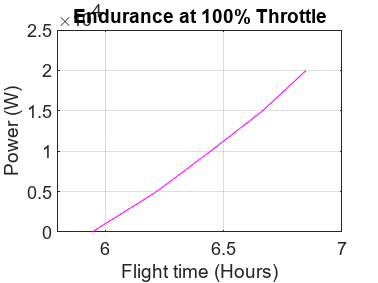


% Graph 
figure(23)
plot(EMTOW_100, CAlt, 'm' )
hold on ,grid on
ylabel ('Power (W)')
xlabel ('Flight time (Hours)')
title ('Endurance at 100% Throttle')

xlim([5.8 7])
ylim ([0, (2.5 * (10^4))])


% Endurance at 90% Throttle (MTOW)
EMTOW_90 = [DesignFuel ./ Fuelc_12000(1,2), DesignFuel ./ Fuelc_14000(1,2), DesignFuel ./ Fuelc_16000(1,2), DesignFuel ./ Fuelc_18000(1,2), DesignFuel ./ Fuelc_20000(1,2)] 

EMTOW_90 =     6.0785    6.3668    6.6299    6.8279    7.0037


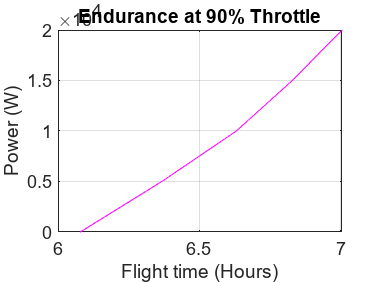


% Graph 
figure(24)
plot(EMTOW_90, CAlt, 'm' )
hold on ,grid on
ylabel ('Power (W)')
xlabel ('Flight time (Hours)')
title ('Endurance at 90% Throttle')




% Endurance at 100% Throttle (MTOW)
EMTOW_80 = [DesignFuel ./ Fuelc_12000(1,3), DesignFuel ./ Fuelc_14000(1,3), DesignFuel ./ Fuelc_16000(1,3), DesignFuel ./ Fuelc_18000(1,3), DesignFuel ./ Fuelc_20000(1,3)] 

EMTOW_80 = 1×5
    6.0785    6.3668    6.7790    6.9822    7.0037


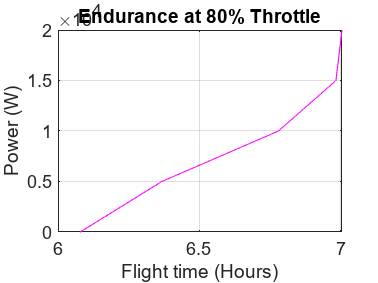


% Graph 
figure(25)
plot(EMTOW_80, CAlt, 'm' )
hold on ,grid on
ylabel ('Power (W)')
xlabel ('Flight time (Hours)')
title ('Endurance at 80% Throttle')

**Appendex**

Vc = 215.435;
CD0 = 0.01186;
CL0 = 0.20245143;
Cla = 5.5909;
CLat = 4.1403;
ac = SS_12000;
S = 16.1651;
St = 3.3;
m = 1066;
g = 9.81;
rho = 1.2251;
cmac = 1.486619;
xcg = ((369.99 * (FrontG-RearG)/(MTOW/g))+RearG) - Datum;
xt = 4.4283;
eta = 1.05;
deda = 0.430609;
Clde = 3.3625

Clde = 3.3625

Cmde = -1.91

Cmde = -1.9100


u0 = Vc;
M  = Vc / ac;
Q = 0.5* Ad_12000 * Vc^2;

%XnP Calculations
c_w      = 2.413; % Chord Length of Wing (m)
c_t      = 1.35; % Chord Length of Tail (m)
x_t      = 10.7; % Leading Edge of Wing to the Leading Edge of Tail (m)
b_t      = 6.4; % Span of Tail (m)
S_t      = ((1.35+0.81)/2)*3*2; % Area of tail (m^2)
Cl       = Clmax_20; % Lift Coefficient (N)
n        = 0.8;
Ct_W     = 0.965; % Wing Chord Tip (m)
Cr_W     = 2.413; % Wing Chord Root (m)
Ct_T     = 0.81; % Tail Chord tip (m)
Cr_T     = 1.35; % Tail Chord Root (m)
Lambda_W = (Ct_W/Cr_W); % Taper Ratio Wing
Lambda_T = 0.6; % Taper Ratio Tail
ArW      = Wingspan^2/WingA; % Aspect Ratio of the Wing
Ar_t     = b_t^2/S_t; % Aspect Ratio of the Tail
CMAC_W   = (2/3)*Cr_W*((1+Lambda_W+Lambda_W^2)/(1+Lambda_W)); % Wing Mean Aerodynamic Chord
CMAC_T   = (2/3)*Cr_W*((1+Lambda_T+Lambda_T^2)/(1+Lambda_T)); % Tail Mean Aerodynamic Chord
e        = (1.78 * (1-(0.045*(ArW^0.68))))-0.64; % Oswald Efficiency Factor
CL_at_2d = 3; % Cl of tail at 2D
CL_aw_2d = 3;% Cl of wing at 2D
CL_at_3d = CL_at_2d/(1+(CL_at_2d/(pi*Ar_t*e))); % Cl of tail at 3D
CL_aw_3d = CL_aw_2d/(1+(CL_aw_2d/(pi*ArW*e)));% Cl of wing at 3D
Xac_w    = c_w/4;
Xac_t    = c_t/4;
Hn_w     = Xac_w/c_w;
Hn_t     = Xac_t/c_t;
lt       = x_t - (CMAC_W*Hn_w)+(CMAC_T*Hn_t);

%Horizontal Tail volume Ratio
deda_W   = (2*CL_aw_3d)/(pi*ArW); % Downwash Change with angle of attack on wing
deda_T   = (2*CL_at_3d)/(pi*Ar_t);% Downwash Change with angle of attack on tail

## Phugoid at 12000ft

QSmu = Q * WingA / ((MTOW / g) * SS_12000);

% Calculate Xu
CTu = -CCd_0

CTu = -0.0056

CDu = 0

CDu = 0

CXu = -(CDu + 2 * CCd_0) + CTu

CXu = -0.0167

Xu  = CXu * QSmu

Xu = -0.0020


% Calculate Zu
CLu = MCruise_12000.^2 / (1 - MCruise_12000.^2) * CClmax_3D

CLu = 0.1030

CZu = -(CLu + 2 * CClmax_3D)

CZu = -0.9412

Zu  = CZu * QSmu

Zu = -0.1155


A = [Xu     -g;
    -Zu/u0   0]

A = 2×2
   -0.0020   -9.8100
    0.0005         0



wn_ph = sqrt( -g / SS_12000 * Zu) % Natural Frequency of Phugoid (Angular)

wn_ph = 0.0590

fn_oh = wn_ph / (2 * pi) % Natural Frequency of Phugoid (Hertz)

fn_oh = 0.0094


DR_ph = -Xu / (2 * wn_ph)% Dumping ratio of a phugoid

DR_ph = 0.0174


wd_ph = wn_ph * sqrt(1-DR_ph^2) % Dumped Frequency of phugoid

wd_ph = 0.0589

T_ph  = 2 * pi /wd_ph % Time taken for the phugoid

T_ph = 106.5906


B = [0 ; 0]

B = 2×1
     0
     0


C = eye(2)

C = 2×2
     1     0
     0     1


D = [0 ; 0]

D = 2×1
     0
     0


## Dutch Roll 12000ft

Dr_xcg = xcg + Datum % Centre of gravity for the Dutch roll

Dr_xcg = 13.0852

Ixx    = MTOW / 2 * 2.5^2 % Moment of inertia at the x axis

Ixx = 4.9111e+05

Iyy    = (1/12) * MTOW * (3 * 2.5^2 + 24^2) % Moment of inertia at the y axis

Iyy = 7.7891e+06

Izz    = (1/12) * MTOW * 25.2^2 % Moment of inertia at the z axis

Izz = 8.3167e+06

Ixz    = MTOW * 1.25 * Dr_xcg % Moment of inertia during dutch role

Ixz = 2.5705e+06


ADr = [0,1; -(Ixx/Iyy) * ((Ad_12000 * SS_12000 * WingA * Wingspan)/(2 * Iyy)), -(Ixz/Iyy) * ((Ad_12000 * SS_12000 * WingA * Wingspan)/(2 * Iyy))]

ADr = 2×2
         0    1.0000
   -0.0007   -0.0037


BDr = [0, 0; ((Ad_12000 * SS_12000 * WingA * Wingspan)/(2 * Iyy)), 0]

BDr = 2×2
         0         0
    0.0111         0


CDr = [1 0;
       0 1]

CDr = 2×2
     1     0
     0     1


DDr = zeros(2)

DDr = 2×2
     0     0
     0     0
